# ECPE 226 - Homework 01 - Perceptron Learning Algorithm (PLA)

Implement a PLA. Train said algorithm and test it on "real" data that will give us statistic on how well it performed computational learning.

% Clean up workspace
clear; close all; clc

## PART 1 - MATLAB CODE

For the first part of this assignment, two separate conditions were required. The first was using a training data size of 10, and then for the second part a training data size of 100 was used. These two conditions were implemented in the same while loop. Also, each condition was repeated 1,000 times to get the mean iterations it took for the PLA to learn and for a mean value of the error rate.

% Define number of training data points for both conditions
n = [10 100];

% Initialize statistics we want to derive from conditions
avg_iterations = zeros(2, 1);
avg_error_rate = zeros(2, 1);

% Loop for condition a & b
for k=1:2
    % Initialize iteration array and error rate array
    t = zeros(1000, 1);
    error_rate = zeros(1000, 1);
    
    % Loop to repeat 1,000 times to get accurate statistics
    for j=1:1000
        % Set data range boundry
        lb = -1;    % lower boundry
        ub = 1;     % upper boundry
    
        % Dimension of dataset
        dim = 2;
    
        % Generate data
        [x, y, ~] = pla_getdata(lb, ub, dim, ((n(k)*10)+n(k)));
    
        % Take first n as training data
        x_training = x(1:n(k),:);
        y_training = y(1:n(k),:);
    
        % Train PLA
        [g, t(j)] = pla(x_training, y_training);
    
        % Get classifications based on final hypothesis, g
        y_hyp = zeros(n(k),1);
        for i = (n(k)+1):((n(k)*10)+n(k))
            y_hyp(i) = sign(dot(g,x(i,:)));
        end
    
        % compare classifications to training data
        comp_arr = (y_hyp == y);
    
        % Caculate wrong classifications made by final guess
        errors = 0; % initialize error counter
        for i=(n(k)+1):((n(k)*10)+n(k))
            if comp_arr(i)==0
                errors = errors + 1;
            end
        end
    
        % Calculate error rate for this run (out of n*10)
        error_rate(j) = (errors/(n(k)*10))*100;   % percent error rate
    end
    
    % Calculate average iterations and error rate of 1,000 runs of PLA
    avg_iterations(k) = mean(t);
    avg_error_rate(k) = mean(error_rate);
end

## PART 1 - PLOTS

The mean amount of iterations it took for the PLA to learn can be seen in the first plot from both the training sample size of 10 and 100. Then in the second plot, the mean error rate is displayed as a percentage of the total "real" data size that was used to test the PLA.

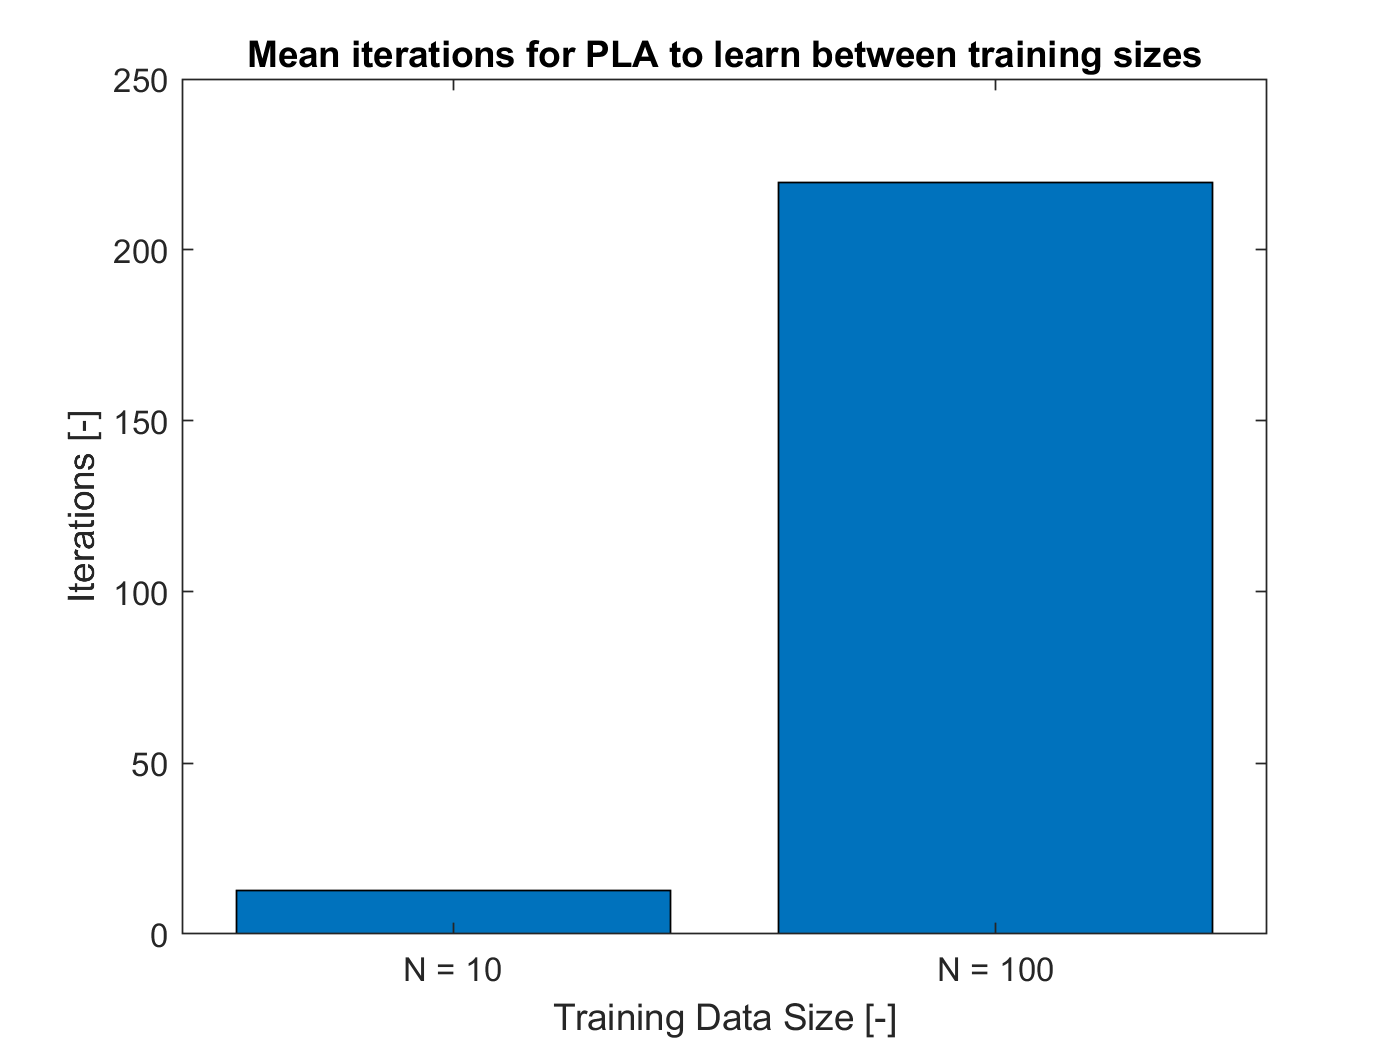

% Plot bar graph of results of PART 1
c = categorical({'N = 10','N = 100'});
bar(c, [avg_iterations(1), avg_iterations(2)])
hold on
title("Mean iterations for PLA to learn between training sizes")
ylabel("Iterations [-]")
xlabel("Training Data Size [-]")

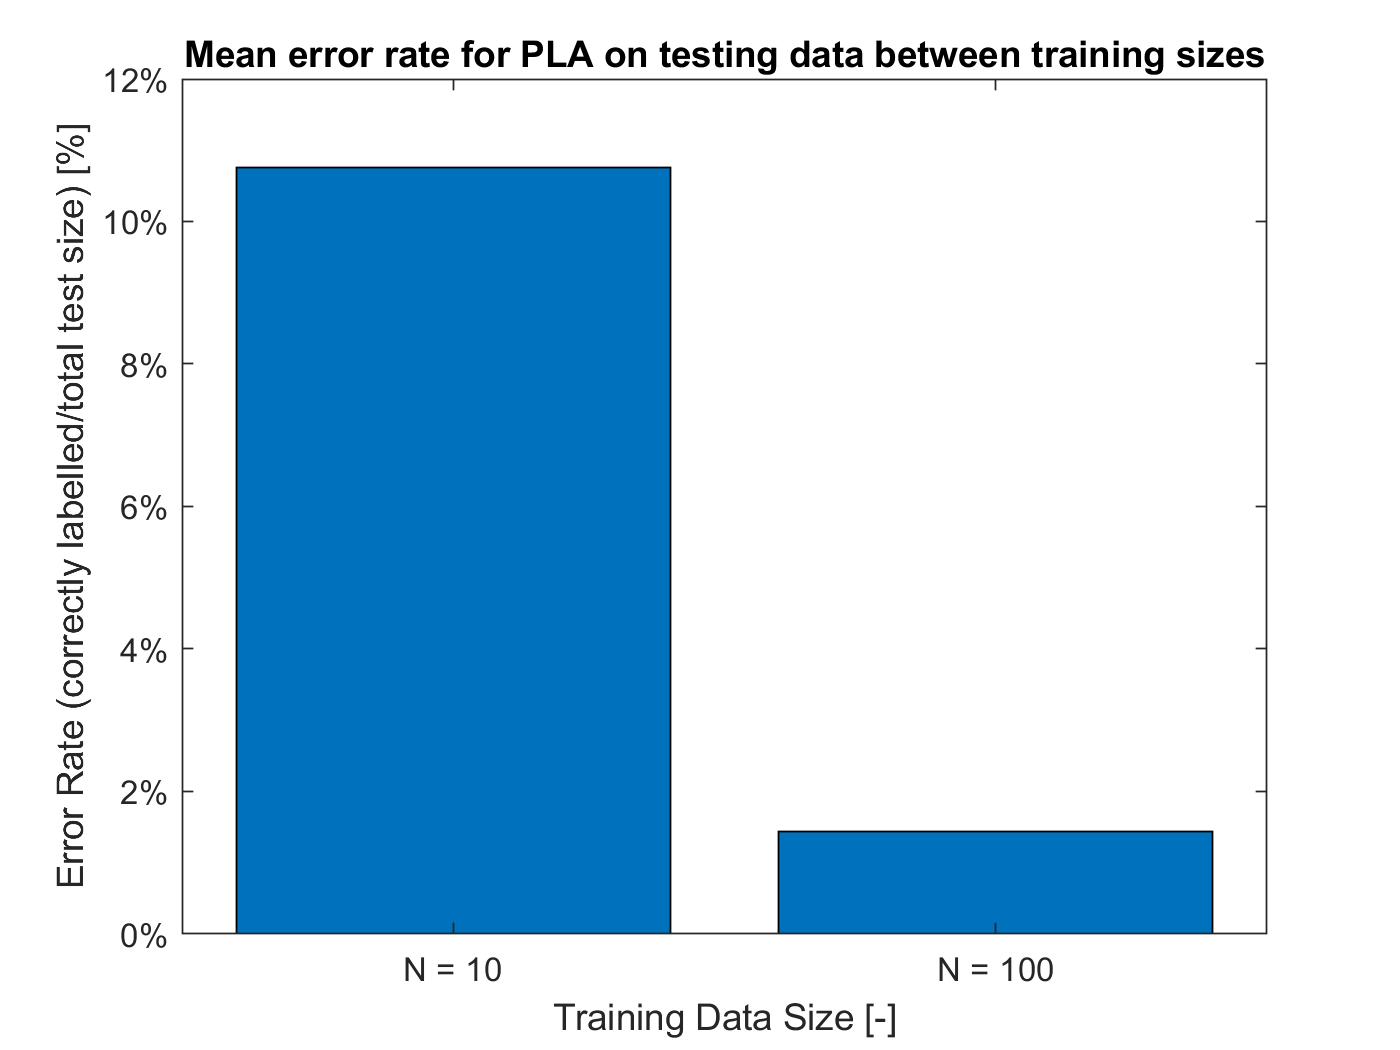

figure
bar(c, [avg_error_rate(1), avg_error_rate(2)])
hold on
title("Mean error rate for PLA on testing data between training sizes")
ylabel("Error Rate (correctly labelled/total test size) [%]")
xlabel("Training Data Size [-]")
ytickformat('percentage')

As seen in the plots, the number of iterations increased as the training size increased. This is most likely due to the additional data points that need to be considered when training the PLA. This would also mean that the final guess from the PLA would be more accurate in the larger training data size. And looking at the second plot, that seems to be the case. As the training data size increased the error rate decreased.

## PART 2 - MATLAB CODE

For the second part of this assignment, four separate conditions were required. All of the conditions used a training data size of 100 and test data size of 10,000. It also limited the iterations of the PLA learning to 1,000. But this time, a signal s(t) was incorporated into updating the weighted vector. This signal was the positive or negative distance from a random training point that would allow the PLA to adjust it's guess according to how far it is to other points instead of blindly moving the geuss until all points were classified correctly.

% Define number of training data points for both conditions
nu = [100 1 0.01 0.0001];

% Initialize statistics we want to derive from conditions
error_rate = zeros(4, 1);

% Initialize data training set
training_data = zeros(100, 16);

% Initialize target function array
f = zeros(3, 4);

% Initialize final guess function array
g = zeros(3, 4);

% Loop for condition a & b
for k=1:4
    
    % Set data range boundry
    lb = -1;    % lower boundry
    ub = 1;     % upper boundry
    
    % Define number of training data points for both conditions
    n = 100;

    % Dimension of dataset
    dim = 2;

    % Generate data
    [x, y, f(:, k)] = pla_getdata(lb, ub, dim, ((n*100)+n));

    % Take first n as training data, also store in array
    x_training = x(1:n,:);
    y_training = y(1:n,:);
    
    training_data(:,((4*k)-3):(k*4)) = [x_training y_training];

    % Train PLA
    [g(:, k), t] = pla_modified(x_training, y_training, nu(k));

    % Get classifications based on final hypothesis, g
    y_hyp = zeros(n,1);
    for i = (n+1):((n*100)+n)
        y_hyp(i) = sign(dot(g(:, k),x(i,:)));
    end

    % compare classifications to training data
    comp_arr = (y_hyp == y);

    % Caculate wrong classifications made by final guess
    errors = 0; % initialize error counter
    for i=(n+1):((n*100)+n)
        if comp_arr(i)==0
            errors = errors + 1;
        end
    end

    % Calculate error rate for this run (out of n*10)
    error_rate(k) = (errors/(n*100))*100;   % percent error rate   
end

## PART 2 - PLOTS

The following plots will show the training data, the target function, the hypothesis function, and the error rate of each learning rate conditions.

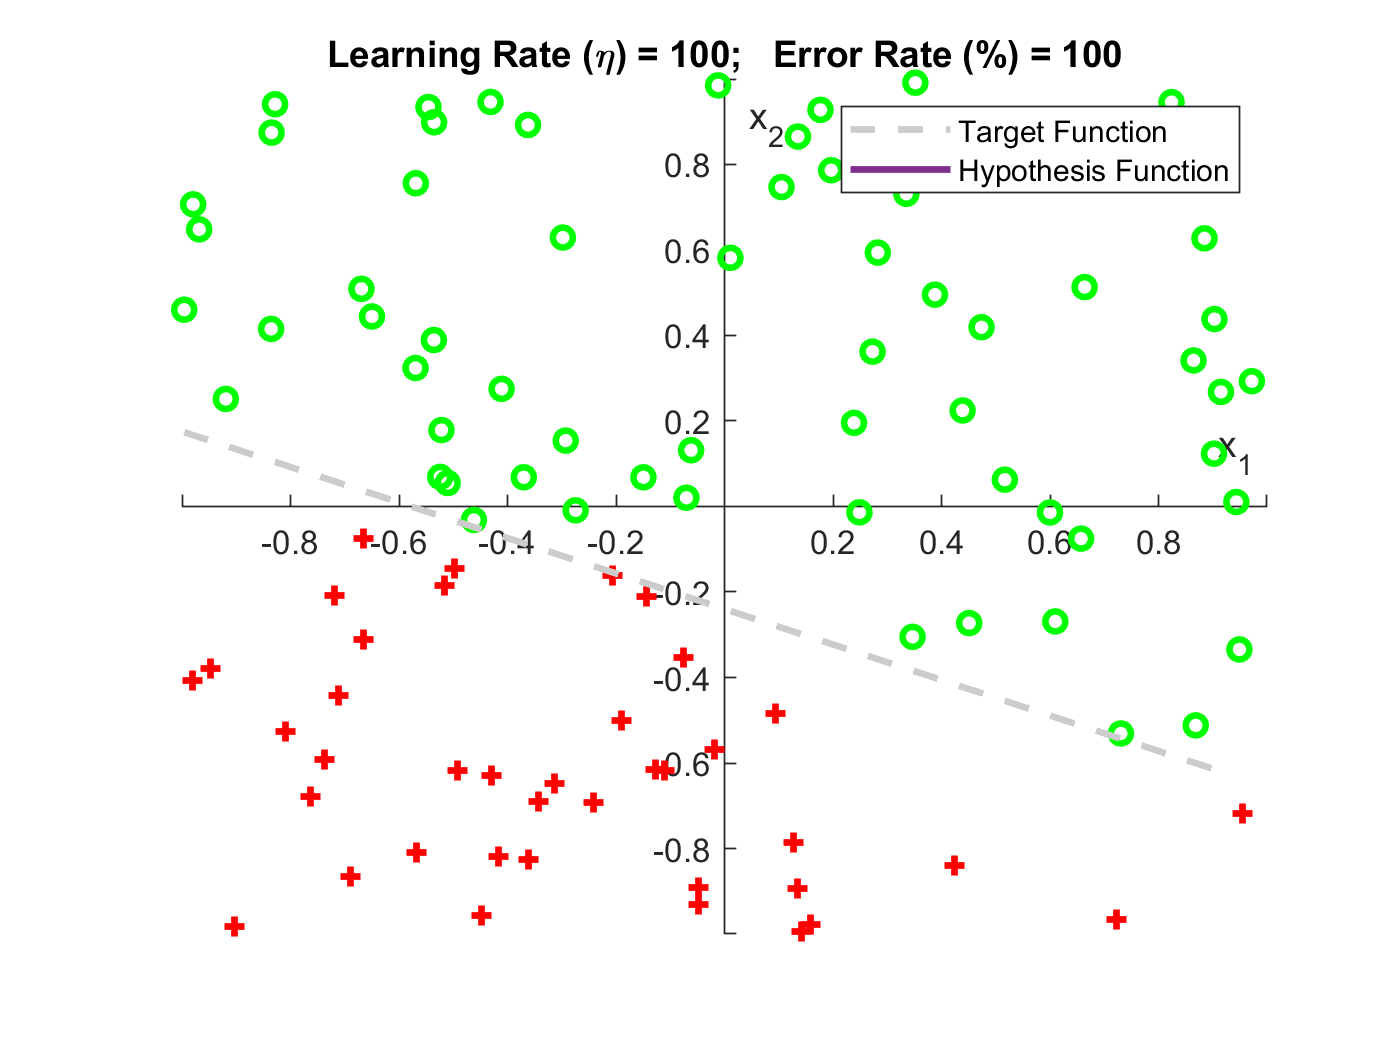

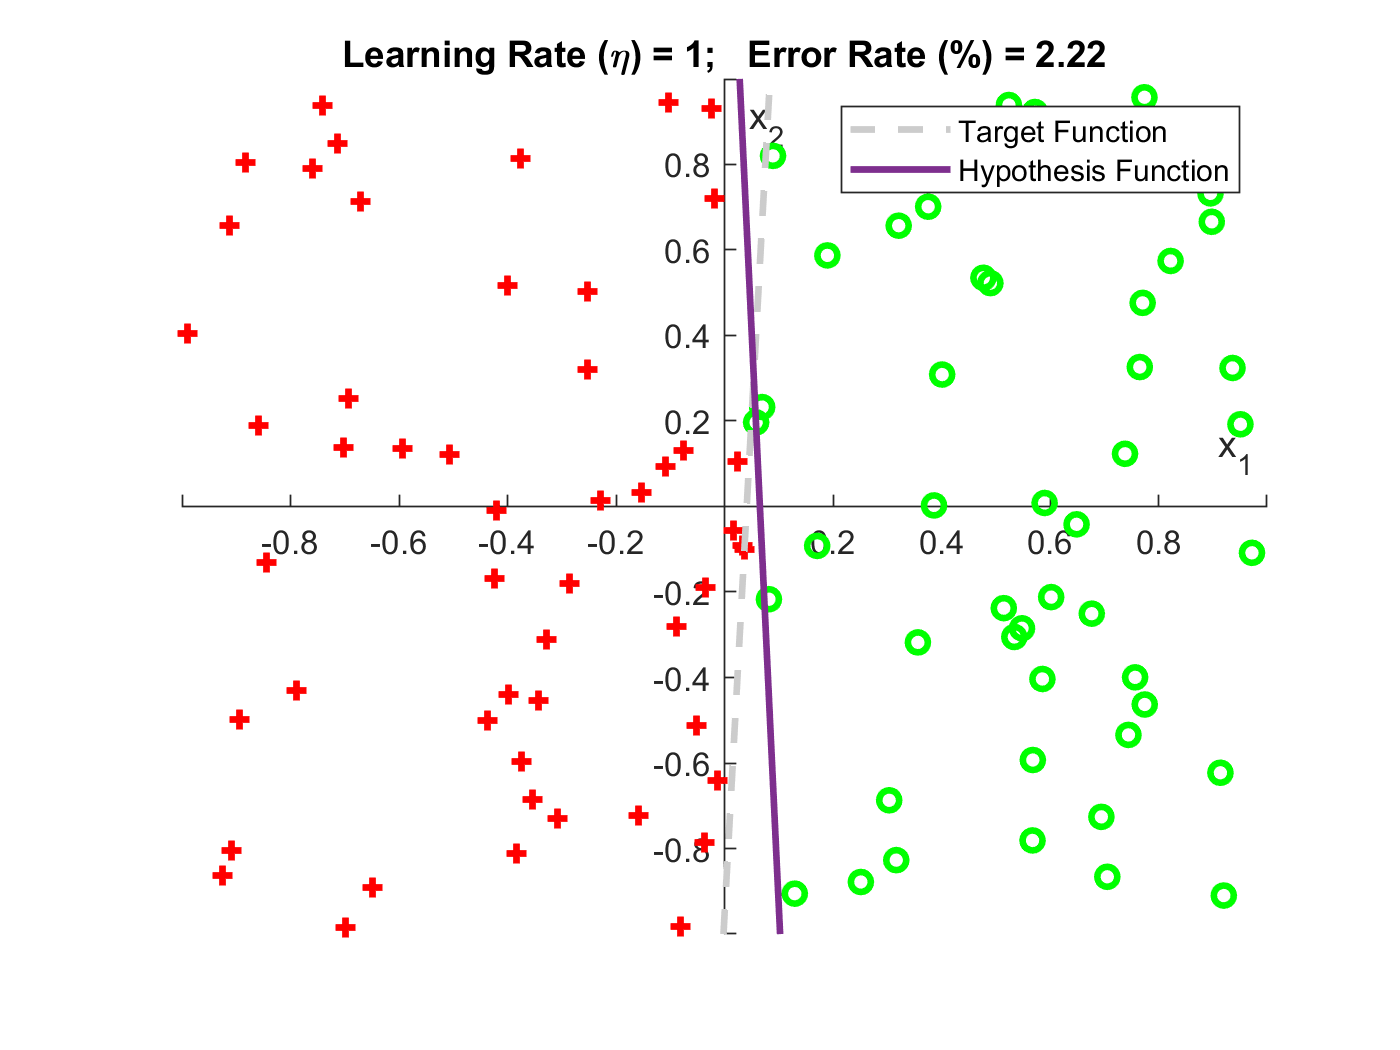

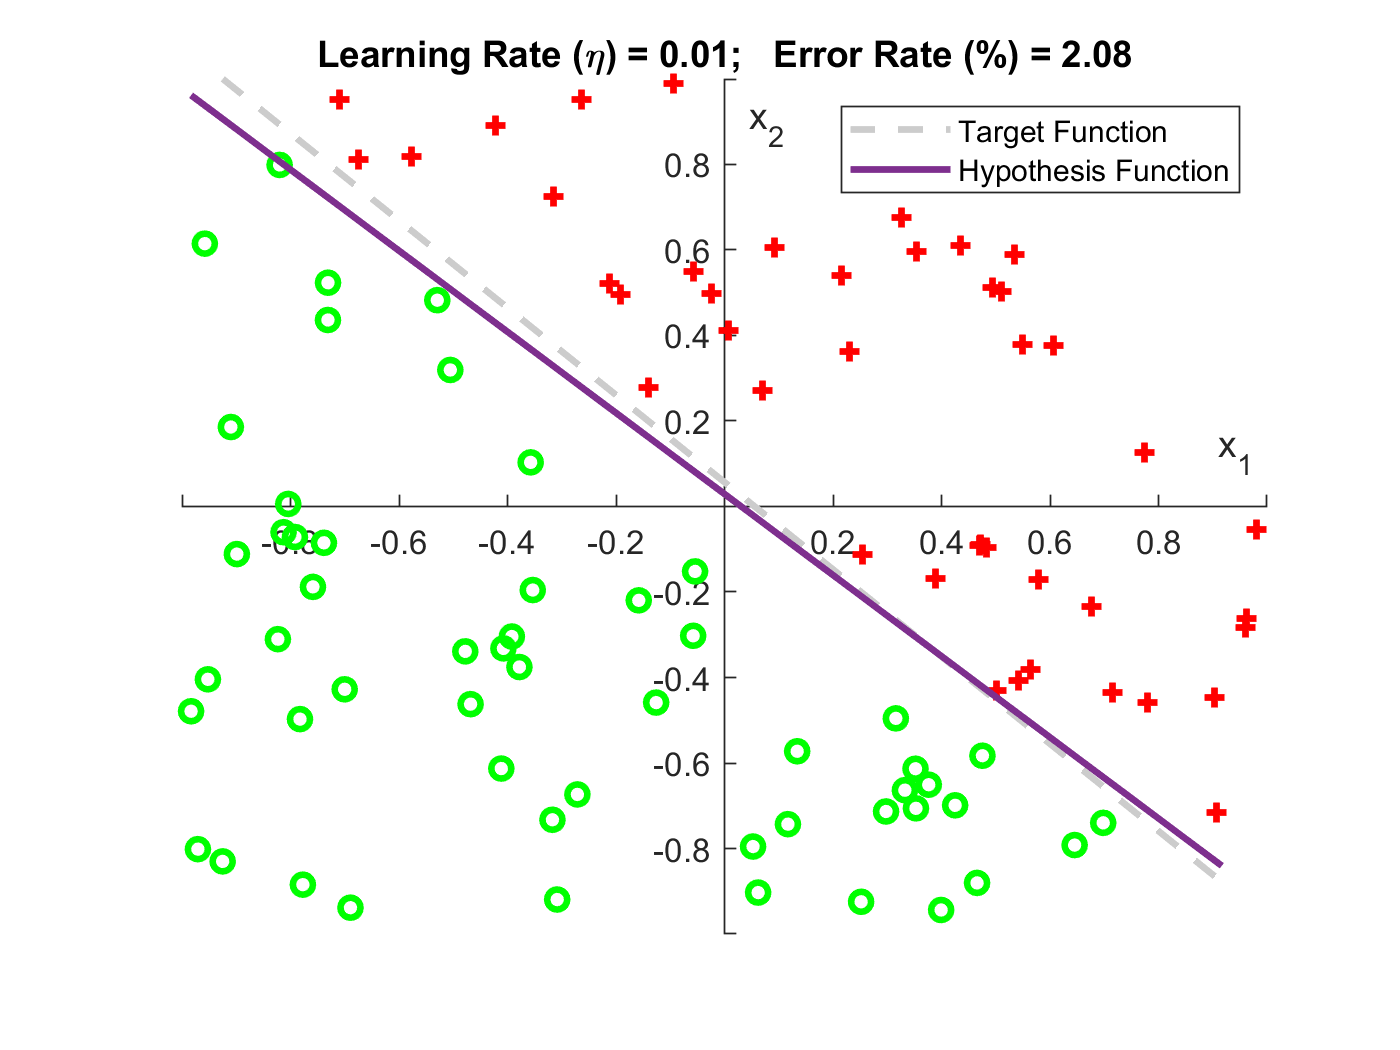

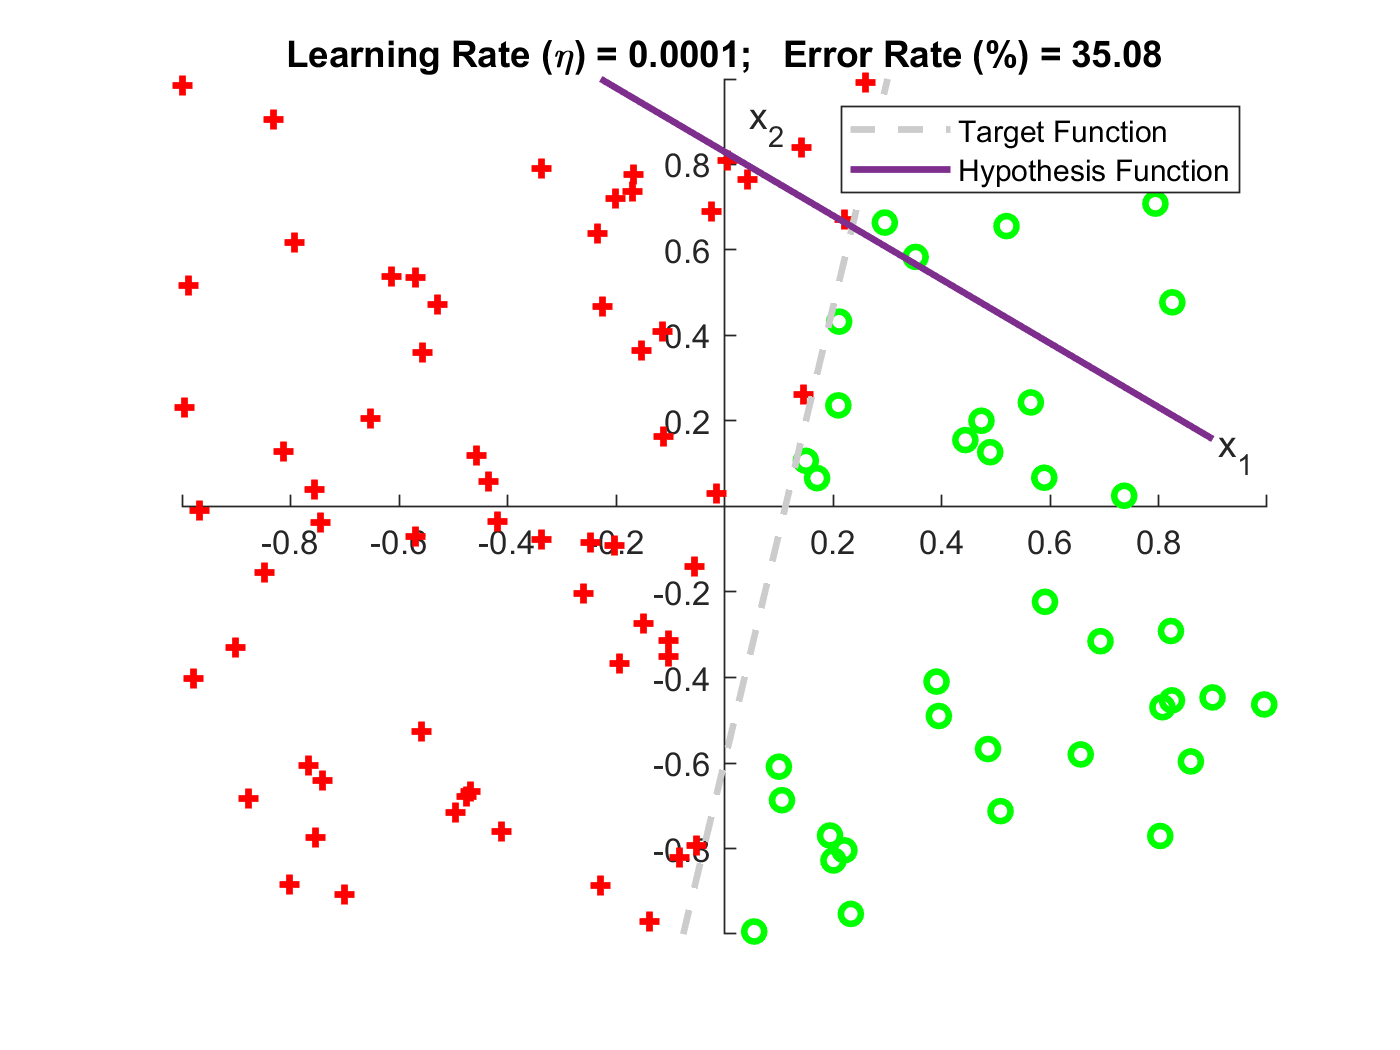

% Loop through each condition and plot the results
for k=1:4

    % Plot the training dataset
    figure
    hold on;
    for i = 1:n % plot data points
        if training_data(i, (4*k)) == 1
            scatter(training_data(i,((4*k)-2)),training_data(i,((4*k)-1)),'r','+','LineWidth',2);
        else
            scatter(training_data(i,((4*k)-2)),training_data(i,((4*k)-1)),'g','o','LineWidth',2);
        end
    end
    axis([-1 1 -1 1])
    xlabel('x_1'); ylabel('x_2');
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    
    % generate data for drawing target function line
    xl = min(training_data(:,((4*k)-2))):0.1:max(training_data(:,((4*k)-2)));
    yl = -(f(2, k)*xl+f(1, k))/f(3, k);
     
    % plot initial target function line
    p1 = plot(xl,yl,'Color',[.8 .8 .8],'LineStyle','--','LineWidth',2);
    
    % generate data for drawing hypothesis line
    y2 = -(g(2, k)*xl+g(1, k))/g(3, k);
     
    % plot hypothesis line
    p2 = plot(xl,y2,'LineWidth',2);
    
    % add title
    title("Learning Rate (\eta) = " + num2str(nu(k)) + ";   Error Rate (%) = " + num2str(error_rate(k)));

    % add legend
    legend([p1, p2],{'Target Function', 'Hypothesis Function'})
end

After looking at the plots, the first learning rate of 100 never provides us with a hypothesis function. This is because the learning rate is too high and thus overshoots, it's like an unstable signal. It oscillates and increases in amplitude to infinity. The second and third plots do provide a hypothesis function with a low error rate. The 0.01 learning rate gets better results, but both learning rates of 1 and 0.01 can be used to give us accurate learning and hypothesis functions. The last one sometimes gives us a hypothesis function, but when it does, the error rate is relatively high. It is an order of magnitude higher than the 1 and 0.01 learning rates, eventhough this is a lower learning rate of 0.0001. The reason for this is that the PLA has been limited to 1,000 iterations which give it no time to improve it's hypothesis function that much. However, even with the limit removed, it could still end up to slow to where the amount of computations would not be worth the time and energy as we have already seen that a learning rate of 1 or 0.01 can get good results. That's why we add a limit on iterations because the learning rate can be too slow that it never gets to the best hypothesis function.